#### Test file for labeling automation algorithm

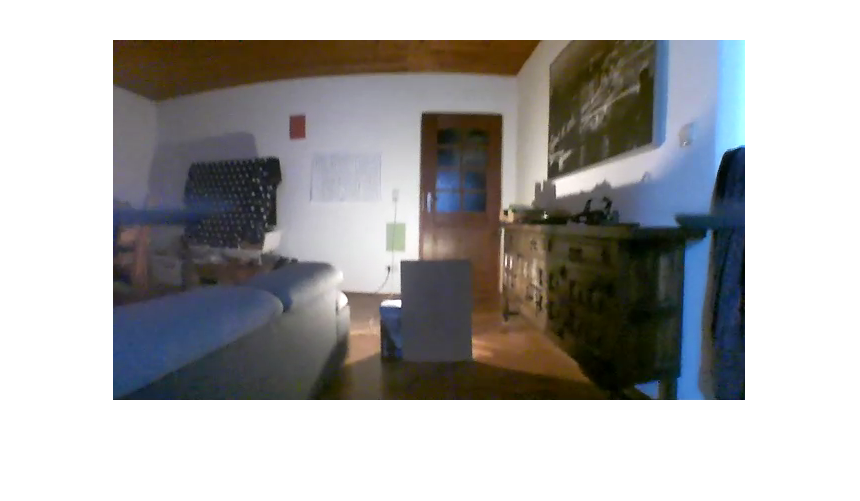

I = imread('testImages\lab1_12.png');
imshow(I)

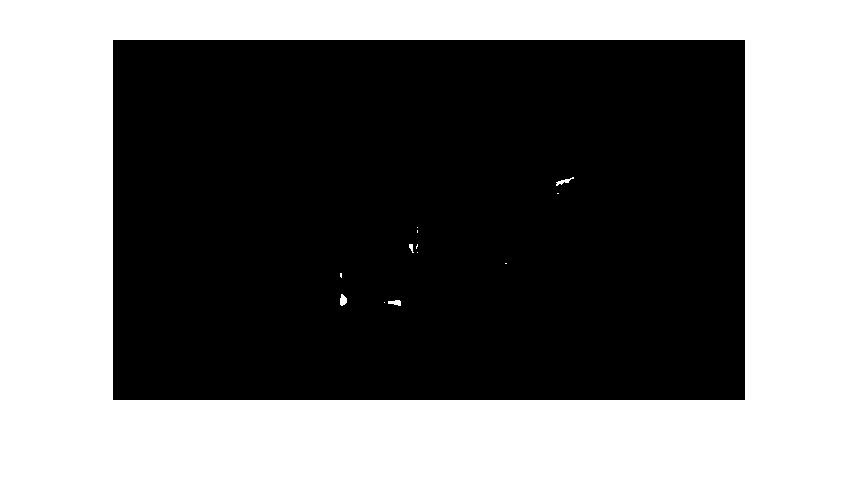

[BW,maskedRGBImage] = extract_red(I);
BW_C = imclose(BW, strel('disk', 1));
BW_f = imfill(BW_C, 'holes');
imshow(BW_f)

s = regionprops(BW_f);
[sortedArray, i] = sort([s.Area], 'descend');
imgSize = size(I);
%maxVals = arrayfun(@(struct)max(struct.Area(:)),s);
%[~, j] = max(maxVals);
for idx = i
    fireBoundBox = s(idx);
    if  (fireBoundBox.BoundingBox(3) > 10 && fireBoundBox.BoundingBox(4) > 10 && fireBoundBox.BoundingBox(3) < (imgSize(2)*0.90))
        f = insertObjectAnnotation(I, 'rectangle',fireBoundBox.BoundingBox, 'fire');
        imshow(f);
        break
    end
    
    
end

parrotObj = parrot()
takeoff(parrotObj);
flightDuration = 0.1;
pause('on')
for idx = 1:10
    % move(parrotObj, flightDuration,'pitch' ,deg2rad(-1));
    moveforward(parrotObj,flightDuration);
    
    pause(1);
    
end
pause('off')
land(parrotObj);
clear parrotObj;

img = imread('testImages\green.bmp');
ret = findGreenEndpoint(img)
fprintf('next %s', ret);

img = imread('testImages\nogreen.bmp');
ret = findGreenEndpoint(img)
fprintf('next %s', ret);

while ~findGreenEndpoint(snapshot(camObj))
    fprintf('looking for green...\n');
    pause(0.5);
end
fprintf('green!');
return;

*Copyright 2019 The MathWorks, Inc.*